help xlsread

  xlsread Read Microsoft Excel spreadsheet file.
 
    *** xlsread is not recommended ***
    See readtable, readmatrix, or readcell.
 
    ----------------------------------------------------
    [NUM,TXT,RAW]=xlsread(FILE) reads data from the first worksheet in the Microsoft
    Excel spreadsheet file named FILE and returns the numeric data in array NUM.
    Optionally, returns the text fields in cell array TXT, and the unprocessed data
    (numbers and text) in cell array RAW.
 
    [NUM,TXT,RAW]=xlsread(FILE,SHEET) reads the specified worksheet.
 
    [NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE) reads from the specified SHEET and RANGE.
    Specify RANGE using the syntax 'C1:C2', where C1 and C2 are opposing corners of
    the region. Not supported for XLS files in BASIC mode.
 
    [NUM,TXT,RAW]=xlsread(FILE,SHEET,RANGE,'basic') reads from the spreadsheet in
    BASIC mode, the default

data = readtable("Lab_6_1.xlsx");
bar(data.Max)

Error using bar
Input arguments must be numeric, datetime, duration or categorical.

cont = char('Ahmedabad','Amritsar','Bangalore','Chennai','Delhi','Jaipur','Jammu','Mumbai');
for i = 1:8,
    gtext (cont (i,:));
end

Hence Jammu has recorded the Max Tempreature of 41 Degrees

data_1 = readtable("Lab_6_2.xlsx")

data_1 = 13×7 table
    RollNo        Name        Accountancy    English    Maths    Economics    BusinessStudies
    ______    ____________    ___________    _______    _____    _________    _______________

       1      {'Akhilesh'}        97           36        47         13              34       
       2      {'Ruchi'   }        69           85        86         51              53       
       3      {'Bhawna'  }        19           72        41         53              40       
       4      {'Isha'    }        76           68        46         11              22       
       5      {'Chetan'  }        55           31        56         99              93       
       6      {'Neeti'   }        84           57        68         30             

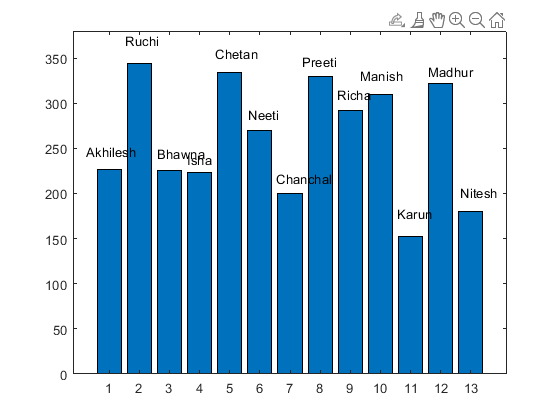

vars = ["Accountancy","English","Maths","Economics","BusinessStudies"];
data_1.TestMean = sum(data_1{:,vars},2);
bar(data_1.TestMean)
cont = char('Akhilesh','Ruchi','Bhawna','Isha','Chetan',...
    'Neeti','Chanchal','Preeti','Richa','Manish','Karun','Madhur','Nitesh');
ylim([0 380])
for i = 1:13,
    gtext (cont (i,:));
end

data_1.Average = mean(data_1{:,vars},2)

data_1 = 13×9 table
    RollNo        Name        Accountancy    English    Maths    Economics    BusinessStudies    TestMean    Average
    ______    ____________    ___________    _______    _____    _________    _______________    ________    _______

       1      {'Akhilesh'}        97           36        47         13              34             227        45.4  
       2      {'Ruchi'   }        69           85        86         51              53             344        68.8  
       3      {'Bhawna'  }        19           72        41         53              40             225          45  
       4      {'Isha'    }        76           68        46         11              22  